clear,clc,close all;
L(1)=Link('revolute','d',0,'a',0,'alpha',pi/2,'offset',pi/2);
L(2)=Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset',-pi/2);
L(3)=Link('prismatic','theta',0,'a',0,'alpha',pi/2,'offset',-0.4318);
L(4)=Link('revolute','d',0.4162,'a',0,'alpha',0,'offset',0);
L(5)=Link('revolute','d',0,'a',0,'alpha',-pi/2,'offset', -pi/2);
L(6)=Link('revolute','d',0,'a',0.0091,'alpha',-pi/2,'offset',-pi/2);

L(1).mdh=1;
L(2).mdh=1;
L(3).mdh=1;
L(4).mdh=1;
L(5).mdh=1;
L(6).mdh=1;

grav = [0,0,-9.81];

L(3).qlim=[0,0.5];

PSM = SerialLink(L)

 
PSM = 
 
noname:: 6 axis, RRPRRR, modDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|     1.5708|
|  2|         q2|          0|          0|    -1.5708|    -1.5708|
|  3|          0|         q3|          0|     1.5708|    -0.4318|
|  4|         q4|     0.4162|          0|          0|          0|
|  5|         q5|          0|          0|    -1.5708|    -1.5708|
|  6|         q6|          0|     0.0091|    -1.5708|    -1.5708|
+---+-----------+-----------+-----------+-----------+-----------+
 



% Generate Cartesian positional trajectory
% n-by-3

Ts = 0.01;
Nums = 500;
t = 0:Ts:Ts*(Nums-1);
r = [linspace(0,0.05,Nums).',linspace(0,0.05,Nums).',linspace(0.0065,-0.05,Nums).'];
dr = diff(r)/Ts;

% initial q is zero
q = zeros(size(r,1),6);
dq = zeros(size(r,1),6);

# Pseudoinverse

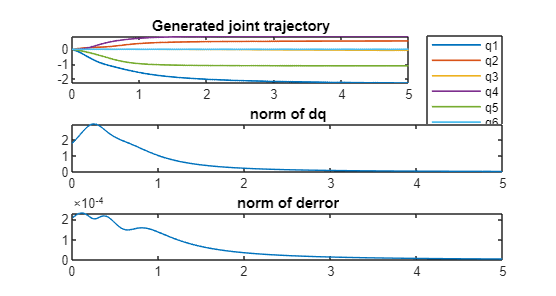

for i=2:size(r,1)
    Ja = getJacobianPSM(q(i-1,:));
    Ja = Ja(1:3,:);
    if rank(Ja)<3
        dq(i-1,:) = pinv(Ja)*dr(i-1,:).';
    else
        dq(i-1,:) = Ja.'*inv(Ja*Ja.')*dr(i-1,:).';
    end
    q(i,:) = q(i-1,:) + Ts*dq(i-1,:);
end
T0e = PSM.fkine(q);
c = zeros(size(r,1),3);
for i=1:size(r,1)
    c(i,:) = T0e(i).t;
end
dc = diff(c)/Ts;
de = dc-dr;

figure('Position', [270,140,750,400])
subplot(3,1,1)
plot(t,q,'LineWidth',1)
title("Generated joint trajectory")
legend('q1','q2','q3','q4','q5','q6', 'Location','eastoutside')

subplot(3,1,2)
plot(t,sqrt(sum(dq.^2,2)))
title("norm of dq")

subplot(3,1,3)
plot(t(2:length(t)),sqrt(sum(de.^2,2)))
title("norm of derror")


% the result is not good as q(3) goes to negative 

# Weighted Pseudoinverse

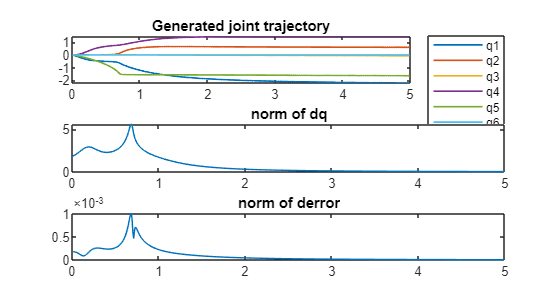

% Weighted pseudoinverse
% initial q is zero
q = zeros(size(r,1),6);
dq = zeros(size(r,1),6);
W = eye(6);
W(1,1) = 1/pi^2;
W(2,2) = 1/pi^2;
W(3,3) = 1/0.5^2;
W(4,4) = 1/(2*pi)^2;
W(5,5) = 1/(2*pi)^2;
W(6,6) = 1/(2*pi)^2;

for i=2:size(r,1)
    Ja = getJacobianPSM(q(i-1,:));
    Ja = Ja(1:3,:);
    if rank(Ja)<3
        dq(i-1,:) = pinv(Ja)*dr(i-1,:).';
    else
        dq(i-1,:) = inv(W)*Ja.'*inv(Ja*inv(W)*Ja.')*dr(i-1,:).';
    end
    q(i,:) = q(i-1,:) + Ts*dq(i-1,:);
end
T0e = PSM.fkine(q);
c = zeros(size(r,1),3);
for i=1:size(r,1)
    c(i,:) = T0e(i).t;
end
dc = diff(c)/Ts;
de = dc-dr;

figure('Position', [270,140,750,400])
subplot(3,1,1)
plot(t,q,'LineWidth',1)
title("Generated joint trajectory")
legend('q1','q2','q3','q4','q5','q6', 'Location','eastoutside')

subplot(3,1,2)
plot(t,sqrt(sum(dq.^2,2)))
title("norm of dq")

subplot(3,1,3)
plot(t(2:length(t)),sqrt(sum(de.^2,2)))
title("norm of derror")

# DLS

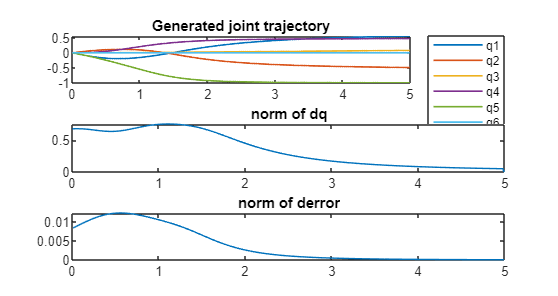

q = zeros(size(r,1),6);
dq = zeros(size(r,1),6);
mu = 0.01;
Im = eye(3);
for i=2:size(r,1)
    Ja = getJacobianPSM(q(i-1,:));
    Ja = Ja(1:3,:);
    dq(i-1,:) = Ja.'*inv(Ja*Ja.' + mu^2*Im)*dr(i-1,:).';
    q(i,:) = q(i-1,:) + Ts*dq(i-1,:);
end

T0e = PSM.fkine(q);
c = zeros(size(r,1),3);
for i=1:size(r,1)
    c(i,:) = T0e(i).t;
end
dc = diff(c)/Ts;
de = dc-dr;

figure('Position', [270,140,750,400])
subplot(3,1,1)
plot(t,q,'LineWidth',1)
title("Generated joint trajectory")
legend('q1','q2','q3','q4','q5','q6', 'Location','eastoutside')

subplot(3,1,2)
plot(t,sqrt(sum(dq.^2,2)))
title("norm of dq")

subplot(3,1,3)
plot(t(2:length(t)),sqrt(sum(de.^2,2)))
title("norm of derror")

# Null-space method

% Maniputability
syms q1 q2 q3 q4 q5 q6
H = 1/12*( ...
    ((q1 - 0)/pi)^2 + ...
    ((q2 - 0)/pi)^2 + ...
    ((q3 - 0.25)/0.5)^2 + ...
    ((q4 - 0)/2*pi)^2 + ...
    ((q5 - 0)/2*pi)^2 + ...
    ((q6 - 0)/2*pi)^2)

$$H = \frac{{\left(2\,q_{3}-\frac{1}{2}\right)}^{2}}{12}+\frac{{q_{1}}^{2}}{12\,\pi^{2}}+\frac{{q_{2}}^{2}}{12\,\pi^{2}}+\frac{{q_{4}}^{2}\,\pi^{2}}{48}+\frac{{q_{5}}^{2}\,\pi^{2}}{48}+\frac{{q_{6}}^{2}\,\pi^{2}}{48}$$


jacobian(H)

$$ans = \left(\begin{array}{cccccc} \frac{q_{1}}{6\,\pi^{2}} & \frac{q_{2}}{6\,\pi^{2}} & \frac{2\,q_{3}}{3}-\frac{1}{6} & \frac{q_{4}\,\pi^{2}}{24} & \frac{q_{5}\,\pi^{2}}{24} & \frac{q_{6}\,\pi^{2}}{24} \end{array}\right)$$

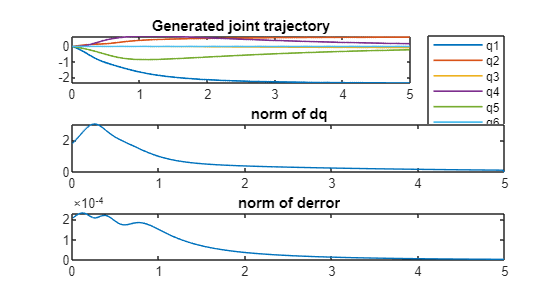

q = zeros(size(r,1),6);
dq = zeros(size(r,1),6);
mu = 0.01;
Im = eye(3);
for i=2:size(r,1)
    Ja = getJacobianPSM(q(i-1,:));
    Ja = Ja(1:3,:);
    Jainv = Ja.'*inv(Ja*Ja.');
    q1 = q(i-1,1);
    q2 = q(i-1,2);
    q3 = q(i-1,3);
    q4 = q(i-1,4);
    q5 = q(i-1,5);
    q6 = q(i-1,6);

    dq0 = -[q1/(6*pi^2), q2/(6*pi^2), (2*q3)/3 - 1/6, (q4*pi^2)/24, (q5*pi^2)/24, (q6*pi^2)/24];
%     dq0 = -[q1/(6*pi^2), q2/(6*pi^2), (2*q3)/3 - 1/6, 0,0,0];
    dq(i-1,:) = Jainv*dr(i-1,:).' + (eye(6) - Jainv*Ja)*dq0.';
    q(i,:) = q(i-1,:) + Ts*dq(i-1,:);
end

T0e = PSM.fkine(q);
c = zeros(size(r,1),3);
for i=1:size(r,1)
    c(i,:) = T0e(i).t;
end
dc = diff(c)/Ts;
de = dc-dr;

figure('Position', [270,140,750,400])
subplot(3,1,1)
plot(t,q,'LineWidth',1)
title("Generated joint trajectory")
legend('q1','q2','q3','q4','q5','q6', 'Location','eastoutside')

subplot(3,1,2)
plot(t,sqrt(sum(dq.^2,2)))
title("norm of dq")

subplot(3,1,3)
plot(t(2:length(t)),sqrt(sum(de.^2,2)))
title("norm of derror")